% E 7.5
clear all

% (a)
syms s
Ls = (s+4)/(s^3 + 10*s^2 + 25*s + 85)

$$Ls = \frac{s+4}{s^{3}+10\,s^{2}+25\,s+85}$$

G = simplify(Ls/(1+Ls))

$$G = \frac{s+4}{s^{3}+10\,s^{2}+26\,s+89}$$

[n, d] = numden(G)

$$n = s+4$$

$$d = s^{3}+10\,s^{2}+26\,s+89$$

num = sym2poly(n)

num =      1     4


den = sym2poly(d)

den =      1    10    26    89


s = double(solve(d == 0,s))

s =   -0.9251 - 3.1725i
  -0.9251 + 3.1725i
  -8.1497 + 0.0000i


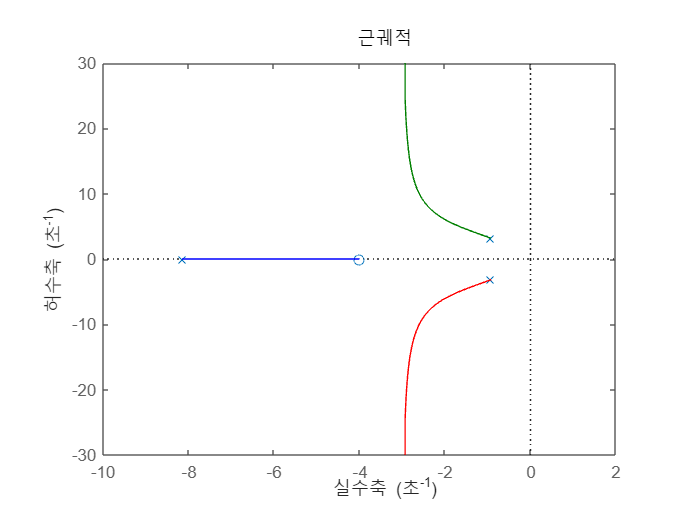

sys = tf(num, den);
figure();
rlocus(sys);

% ans 근궤적의 실수축에 이탈점이 없으므로 구할 수 없다.

% (b)
syms s
poles = solve(n == 0, s)

$$poles = -4$$

zeros = double(solve(d == 0, s))

zeros =   -0.9251 - 3.1725i
  -0.9251 + 3.1725i
  -8.1497 + 0.0000i


sigma = (sum(poles)-sum(zeros))/(numel(poles)-numel(zeros)) % ans 점근선의 중심

$$sigma = -3$$



% (c)
% ans 이탈점이 없으므로 구할 수 없다.